load ('CNC110X69-5.mat');
load ('Samsung_30Q_18650_pack.mat');

addpath("Functions/");
addpath("Simulink/");
addpath("Bode/");

% Step input settings:
stepp.sim_time = 20 * 10^-3; % [ms]
stepp.step_time = 2 * 10^-3; % [ms]
% stepp.ir01 = 0.1;
% stepp.ir02 = pv_data.Impp;
stepp.ir01 = 0.1;
stepp.ir02 = 0.05;

% Switching frequency:
boost.f = 1 * 10^5; % [Hz]
boost.T = 1/boost.f;

% Measurement filter cut-off:
boost.mfc = 2000; %[Hz]
boost.Tmfc = 1/(2*pi*boost.mfc);

% Maximum duty cycle that can be achieved:
boost.D_max = 1 - pv_data.Vmpp/Bat.Ubat_nom; % MPP mode of operation

% Passive elements:
% boost.R = 50;
boost.Rt = 1*10^5;
boost.RL = 10 * 10^-3;
% boost.Ru = Bat.Ru;
boost.Ru = 0.5;
boost.L = 200 * 10^-6;
boost.Cu = 100 * 10^-6;
boost.Ci = 100 * 10^-6;
boost.Cbat = Bat.Qbat_tot/(Bat.Ubat_charged - Bat.Ubat_cut_off);

% Lomna frekv. izlaznog RC kruga:
% f_RC = 1/(2*pi*boost.R*boost.Ci)

## PV resistance:

pv_in.G = 1000;     %[W/m^2]
pv_in.t = 25;       %[deg]
pv_in.ramp = 1;     %[/]

pv = calc_pv_res("Solar_v2", pv_in);

## Plot PV characteristics:

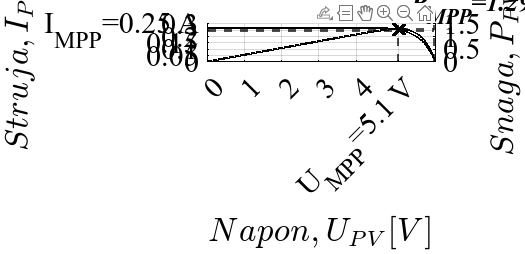

% for 11 x 9 (W x H)
width_px = round(15.52/2.54 * 300); % ~1335 pixels
height_px = round(7.5/2.54 * 300); % ~1146 pixels

fig = figure('Units','pixels','Position',[100 100 width_px height_px]);

% Set default font for axes and text within this figure
set(fig, 'DefaultAxesFontName', 'Times New Roman', 'DefaultAxesFontSize', 24);
set(fig, 'DefaultTextFontName', 'Times New Roman', 'DefaultTextFontSize', 24);

hold on;
grid on;

% --- Left axis: I-V curve ---
yyaxis left
plot(pv.Upv, pv.Ipv, '-k', 'LineWidth', 2);
ylabel("${Struja, I_{PV} [A]}$", 'Interpreter', 'latex');

% --- Right axis: P-V curve (still black) ---
yyaxis right
plot(pv.Upv, pv.Ppv, '-k', 'LineWidth', 2);
ylabel("${Snaga, P_{PV} [W]}$", 'Interpreter', 'latex');

% --- Set both axes black ---
ax = gca;
ax.YColor = 'k';
ax.XColor = 'k';

% --- Common x-axis ---
xlabel("${Napon, U_{PV} [V]}$", 'Interpreter', 'latex');

% --- Add MPP markers ---
yyaxis left
plot(pv.Umpp, pv.Impp, 'xk', 'MarkerSize', 10, 'LineWidth', 3);  % I-V curve
yyaxis right
plot(pv.Umpp, pv.Pmpp, 'xk', 'MarkerSize', 10, 'LineWidth', 3);  % P-V curve

% --- Add Pmpp text label ---
text(pv.Umpp, pv.Pmpp, ...
    sprintf('  P_{MPP}=%.2f W', pv.Pmpp), ...
    'VerticalAlignment','bottom','HorizontalAlignment','left', ...
    'FontSize',20,'FontName','Times New Roman', ...
    'FontWeight','bold','FontAngle','italic', ...
    'Interpreter','tex');
% --- MPP guide lines ---
yyaxis left
xline(pv.Umpp, '--k', 'LineWidth', 1.5);   % vertical line at Umpp
yline(pv.Impp, '--k', 'LineWidth', 1.5);   % horizontal line at Impp

xline(pv.Uoc, '--k', 'LineWidth', 1.5);
yline(pv.Isc, '--k', 'LineWidth', 1.5);

% --- Add x/y ticks only for MPP and remove overlap ---
xt = xticks;
yt = yticks;

% Remove ticks too close to Umpp / Impp (optional)
xt(abs(xt - pv.Umpp) < 0.2 * pv.Umpp) = [];
yt(abs(yt - pv.Impp) < 0.1 * pv.Impp) = [];

% Add the MPP tick positions back
xt = sort([xt, pv.Umpp]);
yt = sort([yt, pv.Impp]);

% Build new labels
xtlbl = string(xt);
ytlbl = string(yt);

% Label Umpp and Impp
[~, ix] = min(abs(xt - pv.Umpp));
xtlbl(ix) = sprintf('U_{MPP}=%.1f V', pv.Umpp);

[~, iy] = min(abs(yt - pv.Impp));
ytlbl(iy) = sprintf('I_{MPP}=%.2f A', pv.Impp);

% Apply new ticks and labels
xticks(xt);
yticks(yt);
xticklabels(xtlbl);
yticklabels(ytlbl);

% --- Final formatting ---
set(gca, 'TickLabelInterpreter', 'tex');
set(findall(gcf,'type','text'), 'Color', 'k');

% --- Set both axes black ---
ax = gca;
ax.YColor = 'k';
ax.XColor = 'k';

grid on;

exportgraphics(gcf, 'graf_pv_characteristic.png', 'Resolution', 300);

## Steady state operating point parameters:

% CCM mode parameters:
ccm_op = ccm_param(boost, Bat, pv_data);
% CCM mode with compensation ramp parameters:
ccm_m_op = ccm_m_param(boost, Bat, pv_data);
Upv0 = ccm_m_op.Upv0

Upv0 = 5.1135

Ipv0 = ccm_m_op.Ipv0

Ipv0 = 0.2514

Ir0 = ccm_m_op.Ir0

Ir0 = 0.2514

Ubat0 = ccm_m_op.Ubat0

Ubat0 = 7.2000

Im0 = ccm_m_op.Im0

Im0 = 0.1387

m0 = ccm_m_op.m0

m0 = 1.3330e+04

ro = ccm_m_op.ro

ro = -2.5983

L_lim = ccm_m_op.L_lim

L_lim = 8.5972e-04

% DCM mode parameters:
dcm_op = dcm_param(boost, Bat, pv_data);
Upv0 = dcm_op.Upv0

Upv0 = 5.1135

Ipv0 = dcm_op.Ipv0

Ipv0 = 0.2514

Ir0 = dcm_op.Ir0

Ir0 = 0.2514

Ubat0 = dcm_op.Ubat0

Ubat0 = 8.4000

m0 = dcm_op.m0

m0 = 1.3330e+04

ro = dcm_op.ro

ro = 1.0858


sim_op = ccm_m_op;

clear Upv0 Ipv0 Ir0 Ubat0 Im0 m0 ro L_lim

## Colors:

% 0, 0, 0;                    % black
% 0, 0, 1;                    % blue
% 1, 0, 0;                    % red
% 0, 1, 0;                    % green
% 0.9290, 0.6940, 0.1250;     % yellow-gold
% 0.8500, 0.3250, 0.0980;     % reddish-orange

myColors = [
    0, 0, 0;                    % black
    0, 0, 1;                    % blue
    1, 0, 0;                    % red
    0, 1, 0;                    % green
];

## CCM, CV tf's:

[ccm_sys, ccm_separate_tfs] = ccm_calc_tfs(boost, ccm_op);

plot_data.t = linspace(0, 0.2*10^-3,1000);
plot_data.labels = {"Full sys", "PT2 with zero", "PT2 aprox", "PT1 aprox"};
plot_data.colors = myColors;
plot_data.y_label = "U_b_a_t [mV]";

% Refrence current:
plot_data.fgtitle = "U_b_a_t response to I_r, CCM-CV";

Ir.full = ccm_separate_tfs.G_Ubat_Ir_full;
Ir.normal = ccm_separate_tfs.G_Ubat_Ir;
Ir.nozero = ccm_separate_tfs.G_Ubat_Ir_nozero;
Ir.red = ccm_separate_tfs.G_Ubat_Ir_red;

ccm_separate_tfs.G_Ubat_Ir

plot_step_responses(Ir, plot_data);

% Input voltage:
plot_data.fgtitle = "U_b_a_t response to U_p_v, CCM-CV";

Upv.full = ccm_separate_tfs.G_Ubat_Upv_full;
Upv.normal = ccm_separate_tfs.G_Ubat_Upv;
Upv.nozero = ccm_separate_tfs.G_Ubat_Upv_nozero;
Upv.red = ccm_separate_tfs.G_Ubat_Upv_red;

plot_step_responses(Upv, plot_data);

clear Ir Upv plot_data;

## CCM,CV (compensation ramp):

[ccm_m_sys, ccm_m_separate_tfs] = ccm_m_calc_tfs(boost, ccm_m_op);

plot_data.t = linspace(0, 0.2*10^-3,1000);
plot_data.labels = {"Full sys", "PT1 aprox"};
plot_data.colors = myColors;
plot_data.linestyles = {'-','--'};
plot_data.y_label = "U_b_a_t [mV]";

% Refrence current:
plot_data.fgtitle = "U_b_a_t response to I_r, CCM-CV";

Ir.full = ccm_m_separate_tfs.G_Ubat_Ir;
Ir.red = ccm_m_separate_tfs.G_Ubat_Ir

Ir = struct with fields:
    full: [1×1 tf]
     red: [1×1 tf]



Gipv = ccm_m_separate_tfs.G_Ubat_Ir

Gipv =
 
        2.478e-06 s + 0.524
  -------------------------------
  5.308e-10 s^2 + 5.981e-05 s + 1
 
Continuous-time transfer function.
Model Properties



wp1 = 1/ccm_m_sys.Tp1

wp1 = 2.0422e+04

wp2 = 1/ccm_m_sys.Tp2

wp2 = 9.2256e+04

wp3 = 1/ccm_m_sys.Tp3

wp3 = 491.6398

Tz1 = ccm_m_sys.Tz1

Tz1 = 4.7284e-06

Tz2 = ccm_m_sys.Tz2

Tz2 = 5.1126e-06

Zeta = ccm_m_sys.zeta

Zeta = 1.2980

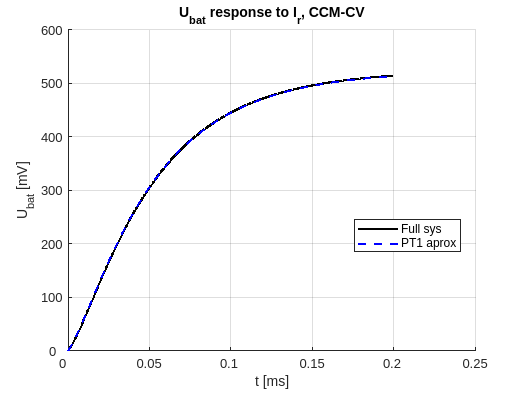


plot_step_responses(Ir, plot_data);


% Input voltage:
plot_data.fgtitle = "U_b_a_t response to U_p_v, CCM-CV";

Upv.full = ccm_m_separate_tfs.G_Ubat_Upv;
Upv.red = ccm_m_separate_tfs.G_Ubat_Upv_red

Upv = struct with fields:
    full: [1×1 tf]
     red: [1×1 tf]


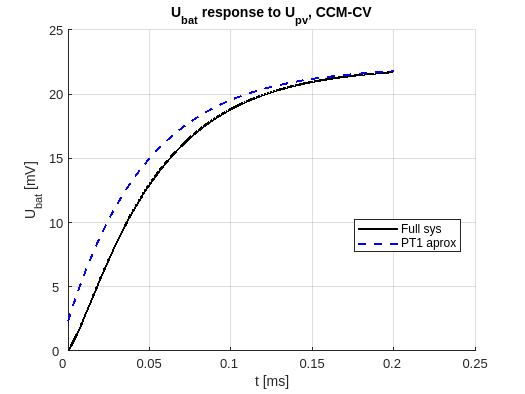


plot_step_responses(Upv, plot_data);


Gipv = ccm_m_separate_tfs.G_Ubat_Ir

Gipv =
 
        2.478e-06 s + 0.524
  -------------------------------
  5.308e-10 s^2 + 5.981e-05 s + 1
 
Continuous-time transfer function.
Model Properties


Gupv = ccm_m_separate_tfs.G_Ubat_Upv

Gupv =
 
       1.131e-07 s + 0.02212
  -------------------------------
  5.308e-10 s^2 + 5.981e-05 s + 1
 
Continuous-time transfer function.
Model Properties



clear Tp1 Tp2 Tz1 Tz2 Zeta;
clear plot_data;

## DCM, CV

[dcm_sys, dcm_separate_tfs] = dcm_calc_tfs(boost, dcm_op);

dcm_separate_tfs.G_Ubat_Ir_full

ans =
 
         2.1e08 s + 6.61e04
  --------------------------------
  3.176e04 s^2 + 6.433e08 s + 2529
 
Continuous-time transfer function.
Model Properties


dcm_separate_tfs.G_Ubat_Ir;

dcm_separate_tfs.G_Ubat_Upv_full

ans =
 
         1.157e07 s + 3642
  --------------------------------
  3.176e04 s^2 + 6.433e08 s + 2529
 
Continuous-time transfer function.
Model Properties


dcm_separate_tfs.G_Ubat_Upv;

dcm_sys.K1

ans = 0.3264

dcm_sys.K2

ans = 0.0180

## Plant model:

% CCM-CV:
[Gp_ccm, plant_ccm_param] = sys_ccm(ccm_m_sys, ccm_m_op, boost);

Gp_ccm

Gp_ccm =
 
       0.001074 s + 1.693
  -----------------------------
  9.96e-08 s^2 + 0.002083 s + 1
 
Continuous-time transfer function.
Model Properties



% DCM-CV:
[Gp_dcm, plant_dcm_param] = sys_dcm(dcm_sys, dcm_op, boost);

Gp_dcm

Gp_dcm =
 
              0.0006638 s - 0.07077
  ---------------------------------------------
  1.619e-12 s^3 + 1.83e-07 s^2 + 0.002124 s + 1
 
Continuous-time transfer function.
Model Properties



clear plot_data;

## Bode plot

z = zero(Gp_ccm);
p = pole(Gp_ccm);
[~, idx_z] = sort(abs(z), 'ascend'); % Sort zeros by magnitude
[~, idx_p] = sort(abs(p), 'ascend'); % Sort poles by magnitude
z_sorted = abs(z(idx_z));
p_sorted = abs(p(idx_p));

p_sorted
z_sorted

w = logspace(0, 6, 1000);

figure();
bode(Gp_ccm);
grid on;

draw_bode(Gp_ccm, w)

% unpackStruct(plant_ccm_param)
% wz = 1/Tz;
% wp1 = 1/Tp1;
% wp2 = 1/Tp2;
% wp3 = 1/Tp3;
% 
% w = logspace(0, 6, 1000);
% 
% [mag_z, ph_z] = Zero_frq_reponse(w, wz);
% [mag_p1, ph_p1] = Pole_frq_response(w, wp1);
% [mag_p2, ph_p2] = Pole_frq_response(w, wp2);
% [mag_p3, ph_p3] = Pole_frq_response(w, wp3);
% 
% mag_dB = 20*log10(K) + mag_z + mag_p1 + mag_p2 + mag_p3;
% phase_deg  = ph_z + ph_p1 + ph_p2 + ph_p3;
% 
% figure();
% bode(Gp_ccm);
% grid on;
% 
% 
% t = tiledlayout(2, 1);
% t.TileSpacing = 'compact';
% t.Padding = 'compact';
% 
% nexttile
% semilogx(w, mag_dB, 'LineWidth', 1.5);
% xline(wz, '--r', 'wz', 'LineWidth', 1.2);
% xline(wp1, '--r', 'wp1', 'LineWidth', 1.2);
% xline(wp2, '--r', 'wp2', 'LineWidth', 1.2);
% xline(wp3, '--r', 'wp3', 'LineWidth', 1.2);
% grid on;
% ylabel('Magnitude (dB)');
% set(gca, 'FontSize', 11);
% 
% nexttile
% semilogx(w, phase_deg, 'LineWidth', 1.5);
% grid on;
% xlabel('Frequency (rad/s)');
% ylabel('Phase (degrees)');
% set(gca, 'FontSize', 11);

## Regulator (symmetrical optimum):

% Textbook:
% Kp = plant_ccm_param.K;
% Tsum = plant_ccm_param.Tp2 + plant_ccm_param.Tp3;
% Ti = 4*Tsum;
% KR = 1/Kp*Ti/(2*Tsum);
% Gr = tf([KR*Ti, KR], [Ti, 0])

% Time constants:
z = zero(Gp_ccm);
p = pole(Gp_ccm);
[~, idx_z] = sort(abs(z), 'ascend'); % Sort zeros by magnitude
[~, idx_p] = sort(abs(p), 'ascend'); % Sort poles by magnitude
z_sorted = abs(z(idx_z));
p_sorted = abs(p(idx_p));

% Open loop gain:
% dL1 = 

% Bjazic
Mpg = 20;
PM = 53;
a = PM/14;
wc = p_sorted(2)/a
wi = wc/a

% w = logspace(0, 6, 1000);
% 
% figure();
% bode(G_full, w);
% grid on;
% 
% draw_bode(G_full, w);

## linear vs nonlinear:

sim_op = dcm_op;

lin = sim("Simulink/Strujni_nacin_v2.slx");

nonlin = sim("Nealinearni_realni_v2.slx");

IL_nonlin = nonlin.get("IL").Data;
Ubat_nonlin = nonlin.get("Ubat").Data;
% Ubat_nonlin = movmean(Ubat_nonlin, 300);
Ubat_lin = lin.get("Ubat").Data;
t = lin.get("Ubat").Time * 1000;

fig = figure;

% % Set paper properties on the figure
% fig.PaperUnits = 'centimeters';
% fig.PaperSize = [21 29.7];           % width x height in inches
% fig.PaperPosition = [0 0 8 4.5];   % position on paper (fill whole paper)

% for 11 x 9 (W x H)
width_px = round(11/2.54 * 300); % ~1335 pixels
height_px = round(9/2.54 * 300); % ~1146 pixels

fig = figure('Units','pixels', 'Position', [100 100 width_px height_px]); % W x H

% Plotting a 3 x 1 array of graphs:
layout = tiledlayout(3,1);
layout.TileSpacing = 'compact';
layout.Padding = 'compact';

% Output voltage:
nexttile;
hold on;
plot(t, Ubat_nonlin, 'b', 'LineWidth', 1.5);
plot(t, Ubat_lin, '--r', 'LineWidth', 2.5);
hold off;
xlabel("\it{t}\rm [ms]");
yl = ylabel("\it{U_{bat}}\rm [V]")
% yl.Position(1) = -1;
legend("Linearni", "Nelinearni");
axis auto;
ax = gca;
ax.FontSize = 24;
ax.FontName = 'Times New Roman';
grid on;

% Error:
nexttile;
error = (Ubat_nonlin - Ubat_lin)*1000;
plot(t, error, 'k', 'LineWidth', 1.5);
yl = ylabel("\it{Pogreška}\rm [mV]");
% yl.Position(1) = -1;
xlabel("\it{t}\rm [ms]");
ax = gca;
ax.FontSize = 24;
ax.FontName = 'Times New Roman';
grid on;

% Struja zavojnice:
nexttile;
plot(t, IL_nonlin, 'k', 'LineWidth', 1.5);
yl = ylabel("\it{i_L}\rm [A]");
% yl.Position(1) = -1;
xlabel("\it{t}\rm [ms]");
ax = gca;
ax.FontSize = 24;
ax.FontName = 'Times New Roman';
grid on;

exportgraphics(gcf, 'graf_ccm_full.png', 'Resolution', 300);

## Pole and zero plot:

% for 11 x 9 (W x H)
width_px = round(15.52/2.54 * 300); % ~1335 pixels
height_px = round(7.5/2.54 * 300); % ~1146 pixels

z1 = zero(ccm_m_separate_tfs.G_Ubat_Ir);
z2 = zero(ccm_m_separate_tfs.G_Ubat_Upv);
p = pole(ccm_m_separate_tfs.G_Ubat_Upv);
p2 = p(1);
p1 = p(2);
clear p;

fig = figure('Units','pixels','Position',[100 100 width_px height_px]);

%% --- Compute text offset based on axis scale ---
ax = gca;
xrange = diff(ax.XLim);
yrange = diff(ax.YLim);

% dx = 0.05 * xrange;   % larger offset than before
% dy = 0.03 * yrange;

% Set default font for axes and text within this figure
set(fig, 'DefaultAxesFontName', 'Times New Roman', 'DefaultAxesFontSize', 24);
set(fig, 'DefaultTextFontName', 'Times New Roman', 'DefaultTextFontSize', 24);

hz1 = plot(real(z1), imag(z1), 'ro', 'MarkerSize', 15, 'LineWidth', 2); hold on;
% text(real(z1), imag(z1) + dy, 'T_{z1}', ...
%                 'Interpreter', 'tex', ...
%                 'HorizontalAlignment', 'right', ...
%                 'VerticalAlignment', 'bottom', ...
%                 'FontSize', 24);

hz2 = plot(real(z2), imag(z2), 'go', 'MarkerSize', 15, 'LineWidth', 2);
% text(real(z2), imag(z2) - dy, 'T_{z2}', ...
%                 'Interpreter', 'tex', ...
%                 'HorizontalAlignment', 'left', ...
%                 'VerticalAlignment', 'top', ...
%                 'FontSize', 24);

plot(real(p1), imag(p1), 'bx', 'MarkerSize', 15, 'LineWidth', 2);
text(real(p1), imag(p1), 'T_{p1}', ...
                'Interpreter', 'tex', ...
                'HorizontalAlignment', 'center', ...
                'VerticalAlignment', 'bottom', ...
                'FontSize', 24);

plot(real(p2), imag(p2), 'bx', 'MarkerSize', 15, 'LineWidth', 2);
text(real(p2), imag(p2), 'T_{p2}', ...
                'Interpreter', 'tex', ...
                'HorizontalAlignment', 'center', ...
                'VerticalAlignment', 'bottom', ...
                'FontSize', 24);

grid on;
xlabel('$Realna$ $os$', 'Interpreter', 'latex');
ylabel('$Imaginarna$ $os$', 'Interpreter', 'latex');
title('$Polovi/Nule$', 'Interpreter', 'latex');

%% --- Legend (zeros only, color-linked) ---
legend([hz1, hz2], {'$T_{z1}$', '$T_{z2}$'}, ...
    'Interpreter', 'latex', ...
    'Location','northeast');

hold off;

exportgraphics(gcf, 'graf_ccm_pz.png', 'Resolution', 300);